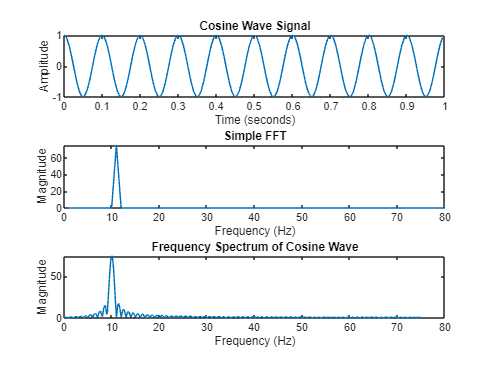

% Define sampling frequency (Fs) in Hz
Fs = 150;  % Choose a sampling frequency higher than the signal frequency

% Define frequency of the cosine wave (f) in Hz
f = 10;

% Create time vector (t) for 1 second with samples based on Fs
t = 0:1/Fs:1-1/Fs; 

% Generate the cosine wave signal (x)
x = cos(2*pi*f*t);

y = fft(x);

% Define length of the FFT (nfft)
nfft = 1024;  % Choose an FFT length that is a power of 2 for efficiency

% --- Part (b): Take the FFT of cosine wave ---
% Compute the Fast Fourier Transform (FFT) of x with padding to nfft length
X = fft(x, nfft);

% Extract the positive frequency components and magnitude (absolute values)
X_pos = X(1:floor(nfft/2));
mag_X = abs(X_pos);

% Create frequency vector (f_pos) based on Fs and nfft for positive frequencies
f_pos = linspace(0, Fs/2, (nfft/2));

% --- Part (c): Take the N point FFT of cosine wave ---
% Use the same approach as in part (b) but with a different nfft value

% --- Plot time domain and frequency domain signals ---
figure(1);

% Plot the cosine wave signal in the time domain
subplot(3,1,1);
plot(t, x);
title('Cosine Wave Signal');
xlabel('Time (seconds)');
ylabel('Amplitude');

subplot(3,1,2);
plot(real(y));
xlim([0 80])
title('Simple FFT');
xlabel('Frequency (Hz)');
ylabel('Magnitude');


% Combine plots for positive frequencies from both FFTs in the frequency domain
subplot(3,1,3);
plot(f_pos, mag_X);
title('Frequency Spectrum of Cosine Wave');
xlabel('Frequency (Hz)');
ylabel('Magnitude');